clc
clear
clf

sim_time = 10;

reference_Input_Grader = 20;
reference_Input_Pos = .3;
Saturation_Rad_pr_s = 1059;

For z

Saturation = Saturation_Rad_pr_s;
Kp = 250;
Ki = 5;
Kd = 550;
stepRef = reference_Input_Pos;
plant_scale = 1.513; %Altitude
transfer_function = tf(0.00727,[1 0 0]);
N=10;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.3828
    TransientTime: 1.4760
     SettlingTime: 1.4760
      SettlingMin: 0.2831
      SettlingMax: 0.3137
        Overshoot: 4.5732
       Undershoot: 0
             Peak: 0.3137
         PeakTime: 0.8081


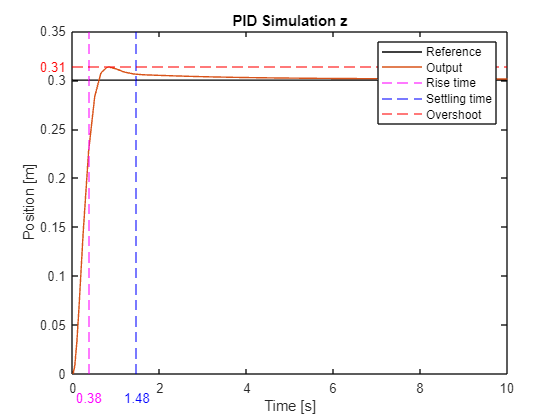

plot(tout,ref,'black',tout, yout)
title('PID Simulation z')
xlabel('Time [s]');
ylabel('Position [m]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.025, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.025, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_Altitude','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  5750 s^2 + 2505 s + 50
  ----------------------
        s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  0.00727
  -------
    s^2
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  41.8 s^2 + 18.21 s + 0.3635
  ---------------------------
         s^4 + 10 s^3
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
          41.8 s^6 + 436.2 s^5 + 182.5 s^4 + 3.635 s^3
  ------------------------------------------------------------
  s^8 + 20 s^7 + 141.8 s^6 + 436.2 s^5 + 182.5 s^4 + 3.635 s^3
 
Continuous-time transfer function.
Model Properties


z_pole = pole(closed)

z_pole =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
 -10.0000 + 0.0000i
  -4.7562 + 3.8122i
  -4.7562 - 3.8122i
  -0.4667 + 0.0000i
  -0.0210 + 0.0000i


z_zero = zero(closed)

z_zero =          0
         0
         0
  -10.0000
   -0.4147
   -0.0210


For attitude roll

Saturation = Saturation_Rad_pr_s;
stepRef = pi/180*reference_Input_Grader;
Kp = 20;
Ki = 0;
Kd = 65;
plant_scale = 0.0185; %I_xx
transfer_function = tf(0.1041,[1 0 0]);
N=20;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.2189
    TransientTime: 2.8866
     SettlingTime: 2.8866
      SettlingMin: 0.3412
      SettlingMax: 0.3654
        Overshoot: 4.6929
       Undershoot: 0
             Peak: 0.3654
         PeakTime: 0.4847


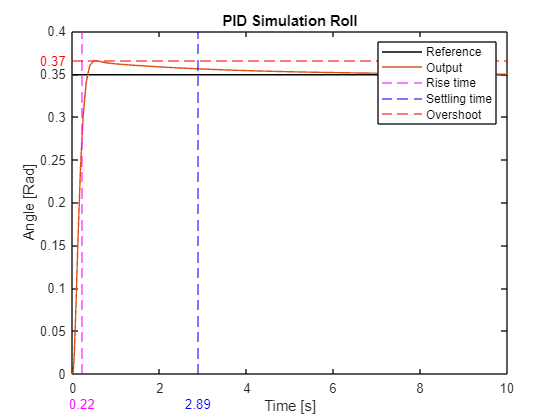

plot(tout,ref,'black',tout, yout)
title('PID Simulation Roll')
xlabel('Time [s]');
ylabel('Angle [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.035, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_Roll','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  1320 s + 400
  ------------
     s + 20
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  0.1041
  ------
   s^2
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  137.4 s + 41.64
  ---------------
   s^3 + 20 s^2
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
         137.4 s^4 + 2790 s^3 + 832.8 s^2
  -----------------------------------------------
  s^6 + 40 s^5 + 537.4 s^4 + 2790 s^3 + 832.8 s^2
 
Continuous-time transfer function.
Model Properties


roll_pole = pole(closed)

roll_pole =    0.0000 + 0.0000i
   0.0000 + 0.0000i
 -20.0000 + 0.0000i
  -9.8413 + 5.8577i
  -9.8413 - 5.8577i
  -0.3175 + 0.0000i


roll_zero = zero(closed)

roll_zero =          0
         0
  -20.0000
   -0.3030


For attitude pitch

Saturation = Saturation_Rad_pr_s;
stepRef = pi/180*reference_Input_Grader;
Kp = 20;
Ki = 0;
Kd = 65;
plant_scale = 0.0201; %I_yy
transfer_function = tf(0.09577,[1 0 0]);
N=20;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.2387
    TransientTime: 3.1765
     SettlingTime: 3.1765
      SettlingMin: 0.3274
      SettlingMax: 0.3654
        Overshoot: 4.6848
       Undershoot: 0
             Peak: 0.3654
         PeakTime: 0.5984


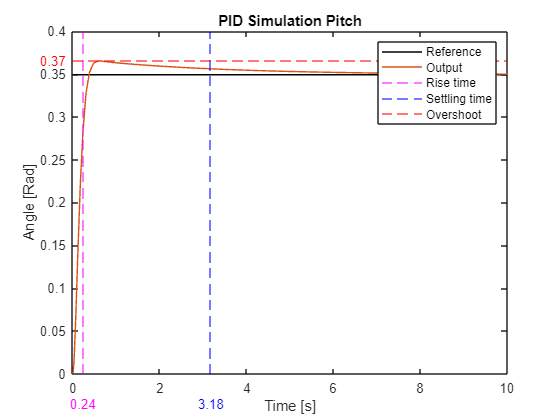

plot(tout,ref,'black',tout, yout)
title('PID Simulation Pitch')
xlabel('Time [s]');
ylabel('Angle [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.035, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_Pitch','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  1320 s + 400
  ------------
     s + 20
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  0.09577
  -------
    s^2
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  126.4 s + 38.31
  ---------------
   s^3 + 20 s^2
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
         126.4 s^4 + 2567 s^3 + 766.2 s^2
  -----------------------------------------------
  s^6 + 40 s^5 + 526.4 s^4 + 2567 s^3 + 766.2 s^2
 
Continuous-time transfer function.
Model Properties


pitch_pole = pole(closed)

pitch_pole =    0.0000 + 0.0000i
   0.0000 + 0.0000i
 -20.0000 + 0.0000i
  -9.8406 + 4.8274i
  -9.8406 - 4.8274i
  -0.3189 + 0.0000i


pitch_zero = zero(closed)

pitch_zero =          0
         0
  -20.0000
   -0.3030


For attitude yaw

Saturation = Saturation_Rad_pr_s;
stepRef = pi/180*reference_Input_Grader;
Kp = 100;
Ki = 0;
Kd = 240;
plant_scale = 0.0286; %I_zz
transfer_function = tf(0.01143,[1 0 0]);
N=20;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.6263
    TransientTime: 3.8656
     SettlingTime: 3.8656
      SettlingMin: 0.3187
      SettlingMax: 0.3651
        Overshoot: 4.5921
       Undershoot: 0
             Peak: 0.3651
         PeakTime: 1.7306


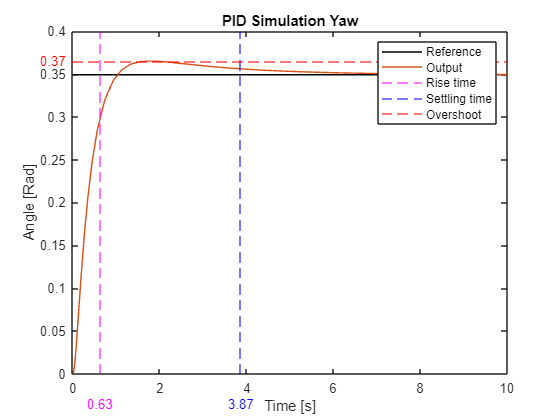

plot(tout,ref,'black',tout, yout)
title('PID Simulation Yaw')
xlabel('Time [s]');
ylabel('Angle [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.035, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_Yaw','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  4900 s + 2000
  -------------
     s + 20
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  0.01143
  -------
    s^2
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  56.01 s + 22.86
  ---------------
   s^3 + 20 s^2
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
        56.01 s^4 + 1143 s^3 + 457.2 s^2
  ---------------------------------------------
  s^6 + 40 s^5 + 456 s^4 + 1143 s^3 + 457.2 s^2
 
Continuous-time transfer function.
Model Properties


yaw_pole = pole(closed)

yaw_pole =          0
         0
  -20.0000
  -16.7349
   -2.7724
   -0.4927


yaw_zero = zero(closed)

yaw_zero =          0
         0
  -20.0000
   -0.4082


For position y

Saturation = 0.35;
stepRef = reference_Input_Pos;
Kp = 0.5;
Ki = 0.02;
Kd = 0.36;
plant_scale = 0.0201; %I_yy
transfer_function = tf([1.022 0 0 ],[0.1041 0 0 0 0]); %y
N=10;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.4708
    TransientTime: 1.7388
     SettlingTime: 1.7388
      SettlingMin: 0.3006
      SettlingMax: 0.3136
        Overshoot: 4.5225
       Undershoot: 0
             Peak: 0.3136
         PeakTime: 1.1426


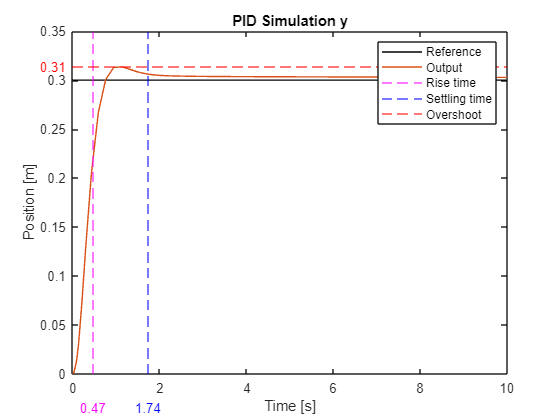

plot(tout,ref,'black',tout, yout)
title('PID Simulation y')
xlabel('Time [s]');
ylabel('Position [m]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.035, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_y','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  4.1 s^2 + 5.02 s + 0.2
  ----------------------
        s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  1.022 s^2
  ----------
  0.1041 s^4
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  4.19 s^4 + 5.13 s^3 + 0.2044 s^2
  --------------------------------
       0.1041 s^6 + 1.041 s^5
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
               0.4362 s^10 + 4.896 s^9 + 5.362 s^8 + 0.2128 s^7
  ---------------------------------------------------------------------------
  0.01084 s^12 + 0.2167 s^11 + 1.52 s^10 + 4.896 s^9 + 5.362 s^8 + 0.2128 s^7
 
Continuous-time transfer function.
Model Properties


y_pole = pole(closed)

y_pole =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
 -10.0000 + 0.0000i
  -3.9879 + 2.8499i
  -3.9879 - 2.8499i


y_zero = zero(closed)

y_zero =          0
         0
         0
         0
         0
         0
         0
  -10.0000
   -1.1832
   -0.0412


For position x

Saturation = 0.35;
stepRef = reference_Input_Pos;
Kp = 0.5;
Ki = 0.02;
Kd = 0.36;
plant_scale = 0.0185; %I_xx
transfer_function = tf([0.9405 0 0 ],[0.09577 0 0 0 0]); %x
N=10;

simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;
figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.4707
    TransientTime: 1.7376
     SettlingTime: 1.7376
      SettlingMin: 0.3006
      SettlingMax: 0.3135
        Overshoot: 4.5167
       Undershoot: 0
             Peak: 0.3135
         PeakTime: 1.1425


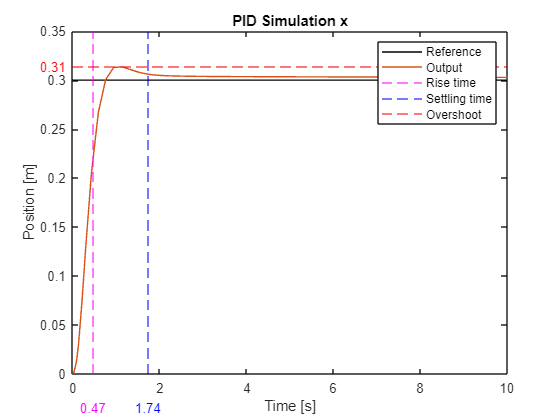

plot(tout,ref,'black',tout, yout)
title('PID Simulation x')
xlabel('Time [s]');
ylabel('Position [m]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-.75, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.3, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.3, -0.035, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

% saveas(gcf,'images/PID_x','epsc')

s = tf('s');
pid = (Kp+Ki*1/s+Kd*N/(1+N*1/s))

pid =
 
  4.1 s^2 + 5.02 s + 0.2
  ----------------------
        s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


transfer_function

transfer_function =
 
  0.9405 s^2
  -----------
  0.09577 s^4
 
Continuous-time transfer function.
Model Properties


direct = pid * transfer_function

direct =
 
  3.856 s^4 + 4.721 s^3 + 0.1881 s^2
  ----------------------------------
       0.09577 s^6 + 0.9577 s^5
 
Continuous-time transfer function.
Model Properties


closed = direct/(1+direct)

closed =
 
                0.3693 s^10 + 4.145 s^9 + 4.54 s^8 + 0.1801 s^7
  ----------------------------------------------------------------------------
  0.009172 s^12 + 0.1834 s^11 + 1.286 s^10 + 4.145 s^9 + 4.54 s^8 + 0.1801 s^7
 
Continuous-time transfer function.
Model Properties


x_pole = pole(closed)

x_pole =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
 -10.0000 + 0.0000i
  -3.9883 + 2.8523i
  -3.9883 - 2.8523i


x_zero = zero(closed)

x_zero =          0
         0
         0
         0
         0
         0
         0
  -10.0000
   -1.1832
   -0.0412




% [pks,locs] = findpeaks(yout);
% times = tout(locs);
% Tu = mean(times(2:end) - times(1))
% Ku = Kp
% 
% Kp = 0.6*Ku
% Ki = 1.2*Ku/Tu
% Kd = 0.075*Ku*Tu
% simData = sim('PID_Sim');
% ref = simData.yout{3}.Values.Data;
% uout = simData.yout{2}.Values.Data;
% yout = simData.yout{1}.Values.Data;
% uoutSat = simData.yout{4}.Values.Data;
% tout = simData.tout;
% omega_max = (max(uout)/0.175)/0.011;
% omega_max_sat = (max(uoutSat)/0.175)/0.011;
% 
% figure()
% S = stepinfo(yout, tout, stepRef)
% plot(tout,ref,'black',tout, yout)
% title('PID Simulation Altitude')
% xlabel('Time [s]');
% ylabel('Angle [Rad]');
% xline(S.RiseTime,'--',Color='[1,0,1]')
% xline(S.SettlingTime,'--',Color='b')
% yline(S.Peak,'--',Color='[1,0,0]')
% text(-1.5, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
% text(S.RiseTime-0.1, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
% text(S.SettlingTime-0.1, -0.017, sprintf('%.2f', S.SettlingTime),Color='b');
% legend('Reference','Output','Rise time','Settling time','Overshoot')

% figure()
% subplot(2,1,1)
% plot(tout,uout)
% title('Simulated control input')
% ylabel('Control signal [Rad]')
% xlabel('Time [s]')
% xlim([0 10])
% 
% subplot(2,1,2)
% plot(tout,uoutSat)
% 
% title('Simulated control input with saturation')
% ylabel('Control signal [Rad]')
% xlabel('Time [s]')
% xlim([0 10])
%saveas(gcf,'images/PID_Example_Control_Signal','epsc')
%saveas(gcf,'images/PID_Control_Signal','epsc')